**HEAD IMAGING - SCATTERED FIELD**

This script computes the scattered electromagnetic field for the realistic 2-D head model. The scattered field is defined as the difference between the total field (head with a pathological blood target) and the incident field (healthy head without target):

-   Es  =  Et  -  Ei

The blood target complex permittivity is obtained from the same 4-Cole-Cole model (Gabriel et al. 1996) used in the background field script. This script is organized as follows:

- Load MRI tissue labels and compute the complex permittivity map

- Load the pre-built FEM mesh and probe node indices

- Map the healthy-head permittivity to mesh cells (perm_bg)

- Define the blood target and build the total permittivity map (perm_tot)

- Solve the Electric field in the domain of imaging

- Save results for the imaging pipeline

clc;
close all;
clear;
addpath('../../Forward_solvers/lib');
addpath('lib');

**OPERATING FREQUENCY AND BACKGROUND MEDIUM**

The simulation frequency and background medium must match the values used in main_generate_background_field exactly. The scalar materials.background_epsc is the complex relative permittivity of the coupling medium surrounding the head.

sim.f               = 1e9;
sim.omega           = 2*pi*sim.f;
materials.background_epsc = 20 - 1i*1;

**LOAD MRI LABELS**

The MRI slice is stored as a grayscale image encoded in the range [0, 255]. The pixel values are linearly mapped to integer tissue labels [0, 11] that identify 12 distinct tissue classes (0=Background, 1=CSF, 2=Gray Matter, 3=White Matter, 4=Fat, 5=Muscle, 6=Muscle/Skin, 7=Skull, 8=vessels, 9=around fat, 10=dura matter, 11=bone marrow).

The image resolution is the physical size of each pixel in meters. It is used by map_permittivity_to_mesh to align the pixel grid with the mesh coordinate system.

label_data = load("MRI_labels/p01.mat");
labels     = round(double(label_data.patient.slice) * 11 / 255);
resolution = 0.5e-3;

**COMPUTE DIELECTRIC MAPS - 4-COLE-COLE MODEL**

The function compute_dielectric_maps assigns a complex relative permittivity value to each pixel based on its tissue label, using the 4-Cole-Cole model:

-   eps*(omega) = eps_inf + sum_n { Delta_n / [1 + (j*omega*tau_n)^(1-alpha_n)] } - j*sigma/(omega*eps0)

Parameters for each tissue class come from Gabriel et al. (1996). The output perm_matrix is a struct with fields .real, .imag, and .complex, each a 2-D map of the same size as labels.

perm_matrix = compute_dielectric_maps(labels, sim.f);


Frequency: 1000.0000 MHz
Tissue                 eps'       eps''  sigma_eff (S/m)
---------------------------------------------------------
Background           1.0000      0.0000       -0.000000
CSF                 68.4385    -44.1324        2.455199
Gray Matter         52.2823    -17.7132        0.985428
White Matter        38.5773    -11.1790        0.621916
Fat                  5.4470     -0.9617        0.053503
Muscle              54.8111    -17.5833        0.978203
Muscle/Skin         45.7110    -15.8437        0.881425
Skull               12.3633     -2.7980        0.155660
Vessels             61.0650    -28.4535        1.582938
Around Fat          11.2943     -2.0920        0.116382
Dura Mater          44.2008    -17.8549        0.993314
Bone Marrow          5.4854     -0.7784        0.043304



**LOAD PRE-BUILT FEM MESH**

The FEM mesh was generated externally from the patient anatomy and saved as a .mat file. The key fields are:

-   verts                 :    (N x 3) vertex coordinates [m] - includes a z column set to zero

-   cells                  :    (M x 3) triangle connectivity (1-based node indices)

-   idx_cells_DoI   :    global indices of cells inside the Domain of Interest

-   Ind_probes      :    node indices of the antenna probe positions

mesh_data     = load("Mesh/mesh_p01.mat");
verts         = mesh_data.verts;
verts(:,3)    = [];
cells         = mesh_data.cells;
idx_cells_DoI = mesh_data.idx_cells_DoI;
probeNodes    = mesh_data.Ind_probes;

**MAP BACKGROUND PERMITTIVITY TO MESH CELLS**

The healthy-head permittivity is mapped onto the mesh cells. This is the baseline distribution: no pathological target is present. It is used to compute the incident field Ei inside the for loop. The output perm_bg is a struct with fields .real, .imag, and .complex.

The scenario struct is built to match the convention used by the plotting functions.

perm_bg = map_permittivity_to_mesh( ...
    perm_matrix.complex, verts, cells, resolution, idx_cells_DoI, materials.background_epsc);

scenario.mesh.Nodes    = verts';
scenario.mesh.Elements = cells';
scenario.cellsDOI      = idx_cells_DoI;

**TARGET DEFINITION - BLOOD (4-COLE-COLE MODEL)**

The target represents a pathological lesion with blood-like dielectric properties. The complex permittivity of blood is extracted directly from the same 4-Cole-Cole model already implemented in compute_dielectric_maps (label 8 = Vessels/Blood, Gabriel et al. 1996). This guarantees consistency with the material database used throughout the pipeline.

The 4-Cole-Cole model for blood at 1 GHz produces:

-   eps_inf = 4,  Delta_1 = 56 (tau_1 = 8.4 ps),  Delta_2 = 5200 (tau_2 = 133 ns),  sigma = 0.70 S/m

The target position and radius are the only free parameters.

% Blood complex permittivity from the 4-Cole-Cole model (label 8)
blood_perm   = compute_dielectric_maps(8 * ones(1), sim.f, 'verbose', false);
target.epsc  = blood_perm.complex(1, 1);

target.center = [0.00, 0.00];   % [m]
target.radius = 0.015;          % [m]

fprintf('Blood: eps_r = %.2f,  sigma_eff = %.3f S/m\n', ...
    real(target.epsc), -imag(target.epsc) * sim.omega * 8.854187817e-12);

Blood: eps_r = 61.06,  sigma_eff = 1.583 S/m


**BUILD TOTAL PERMITTIVITY MAP**

Start from the healthy-head map perm_bg and override the cells that fall inside the target radius with the blood complex permittivity. The result perm_tot is a struct with the same fields as perm_bg.

% Cell centroids (2-D)
centroids = (verts(cells(:,1),:) + ...
             verts(cells(:,2),:) + ...
             verts(cells(:,3),:)) / 3;

% Cells inside the target
dist_to_target = sqrt((centroids(:,1) - target.center(1)).^2 + ...
                      (centroids(:,2) - target.center(2)).^2);
idx_target = intersect(find(dist_to_target <= target.radius), idx_cells_DoI);

% Total permittivity map
perm_tot_complex         = perm_bg.complex;
perm_tot_complex(idx_target) = target.epsc;

perm_tot.complex = perm_tot_complex;
perm_tot.real    = real(perm_tot_complex);
perm_tot.imag    = imag(perm_tot_complex);

fprintf('Target: %d cells assigned (radius = %.1f mm)\n', ...
    numel(idx_target), target.radius * 1e3);

Target: 5658 cells assigned (radius = 15.0 mm)


**PERMITTIVITY VISUALIZATION**

Compare the background and total permittivity maps to verify that the blood target region is correctly assigned.

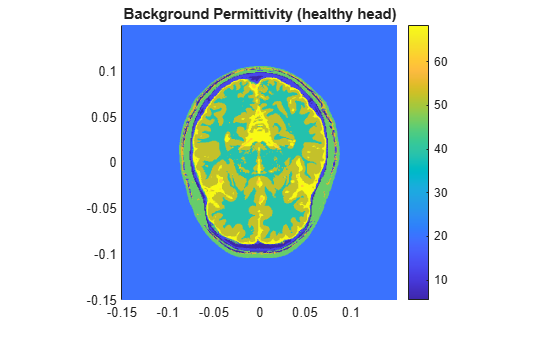

plotPermittivity(...
    scenario.mesh,...
    perm_bg.real,...
    'Background Permittivity (healthy head)');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

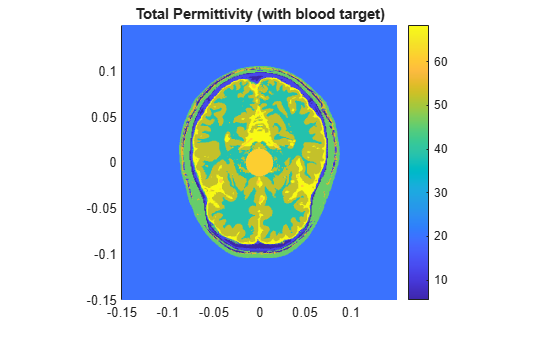


plotPermittivity(...
    scenario.mesh,...
    perm_tot.real,...
    'Total Permittivity (with blood target)');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

**FORWARD FEM SOLUTION**

The function fem2d() computes the electromagnetic field for both scenarios generated by the antenna array inside the heterogeneous dielectric medium.


current = 1e-3;

% Incident field homogeneous DOI
[Everts_i, Ecells_i, ] = fem2d(...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm_bg.complex,...
    sim.f,...
    probeNodes,...
    materials.background_epsc,...
    [], current);

% Total field homogeneous DOI
[Everts_t, Ecells_t, Area] = fem2d(...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm_tot.complex,...
    sim.f,...
    probeNodes,...
    materials.background_epsc,...
    [], current);

Ecells_sct = Ecells_t - Ecells_i;
Eprobes_i = Everts_i(probeNodes,:);
Eprobes_t = Everts_t(probeNodes,:);

**FIELD VISUALIZATION**

The electric fields generated by one transmitting antenna are visualized:

- Incident field magnitude and phase

- Total field magnitude and phase

- Scattered field magnitude and phase

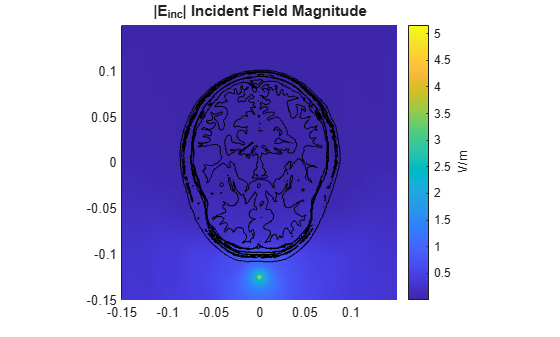

boundaries_struct = load("MRI_labels/boundaries.mat");
boundaries = boundaries_struct.boundaries;

selectedAntenna = 1;

plotField_head(...
    scenario,...
    abs(Ecells_i(:, selectedAntenna)),...
    boundaries,...
    '|E_{inc}| Incident Field Magnitude','V/m');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

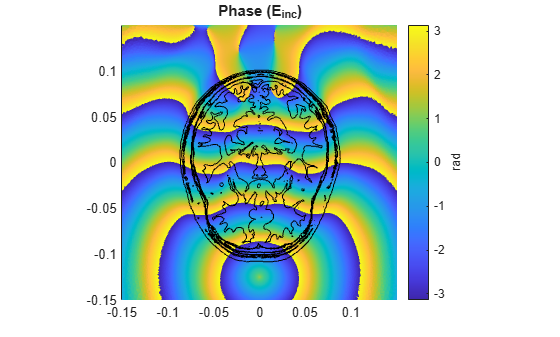


plotField_head(...
    scenario,...
    angle(Ecells_i(:, selectedAntenna)),...
    boundaries,...
    'Phase (E_{inc})','rad');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

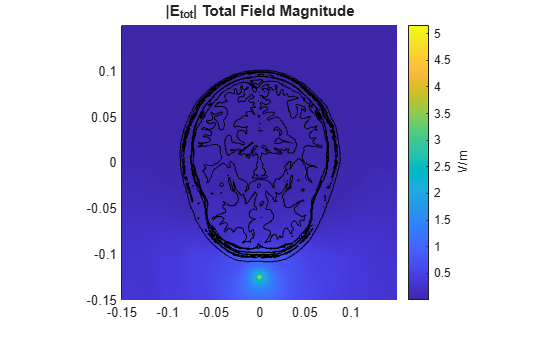


plotField_head(...
    scenario,...
    abs(Ecells_t(:, selectedAntenna)),...
    boundaries,...
    '|E_{tot}| Total Field Magnitude','V/m');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

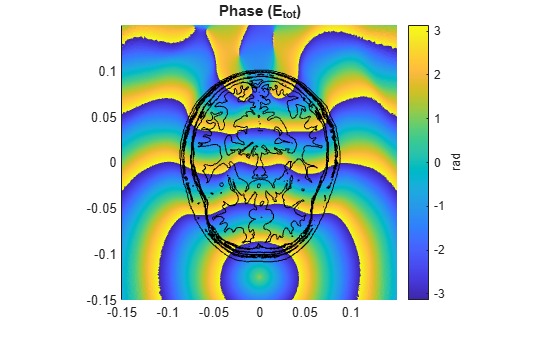


plotField_head(...
    scenario,...
    angle(Ecells_t(:, selectedAntenna)),...
    boundaries,...
    'Phase (E_{tot})','rad');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

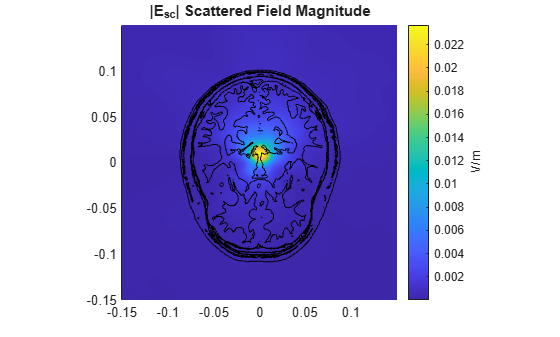


plotField_head(...
    scenario,...
    abs(Ecells_sct(:, selectedAntenna)),...
    boundaries,...
    '|E_{sc}| Scattered Field Magnitude','V/m');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

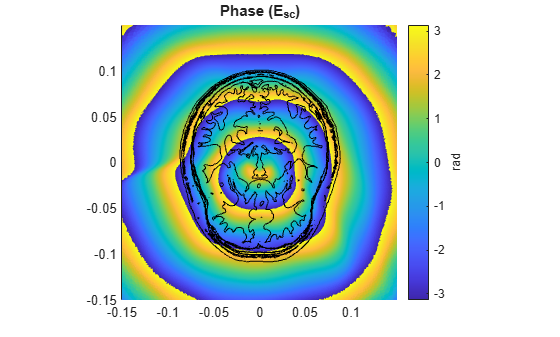


plotField_head(...
    scenario,...
    angle(Ecells_sct(:, selectedAntenna)),...
    boundaries,...
    'Phase (E_{sc})','rad');
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

**SAVE RESULTS**

Two files are exported:

- scattered_fields.mat

- scattered field matrix and supporting field data

- geometry_sf.mat

- new mesh data used for data generation

nameSF  = 'results/scattered_fields';
nameGEO = 'results/geometry_sf';

freq = sim.f;

save([nameSF, '.mat'],...
    'Eprobes_t',...
    'Eprobes_i',...
    'perm_tot',...
    'current',...
    'freq');

% Save new mesh geometry (different from geometry.mat used for reconstruction)

verts_sf      = scenario.mesh.Nodes';
cells_sf      = scenario.mesh.Elements';
Ind_probes_sf = probeNodes;

save([nameGEO, '.mat'],...
    'verts_sf',...
    'cells_sf');